# WaveMarkChan_demo.mlx

S = load(fullfile(fileparts(which('WaveMarkChan')),'kjx021I01_i02_spliced_30_wm.mat'));

traces = S.nw_3.values;

codes = S.nw_3.codes;

yy = timestamps2binned(S.nw_3.times,0,20,17000,'normal');

wm = WaveMarkChan(yy, 0, 17000, codes, traces, S.nw_3.scale, S.nw_3.offset, S.nw_3.trigger, 'nw_3')

wm =   WaveMarkChan with properties:

              Traces: [1618×40 double]
               Scale: 1.5259e-04
              Offset: -0.0200
             Trigger: 11
                Data: [340001×1 double]
    IsMarkerFilterOn: 0
        MarkerFilter: [256×4 table]
          MarkerName: [256×4 table]
            TextMark: {1618×1 cell}
         MarkerCodes: [1618×4 table]
                 ISI: [1617×1 double]
         InstantRate: [1615×1 double]
          TimeStamps: [1618×1 double]
          FiringRate: 80.9000
             NSpikes: 1618
               Stats: [1×1 struct]
           ChanTitle: 'nw_3'
            DataUnit: 'mV'
               Start: 0
               SRate: 17000
              Header: [1×1 struct]
                Path: ''
          ChanNumber: 0
           SInterval: 5.8824e-05
              Length: 340001
             MaxTime: 20
            TimeUnit: 'second'


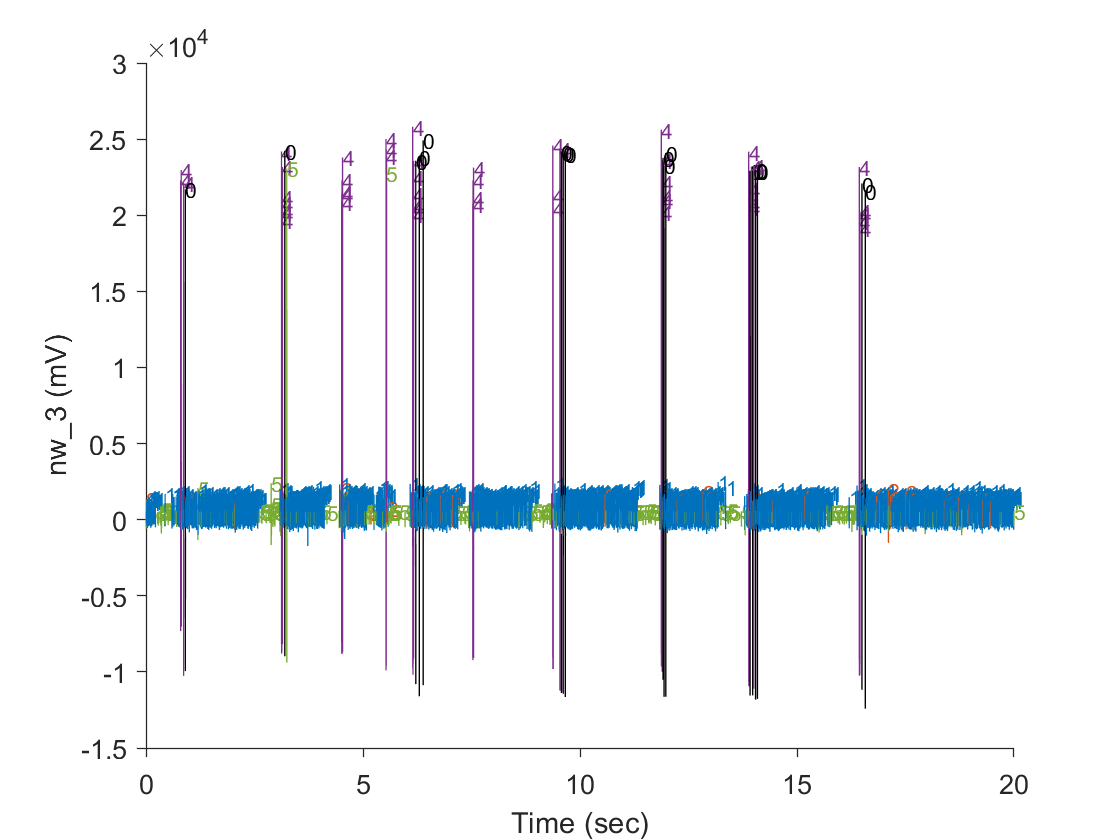

ans = struct with fields:
    fig: [1×1 Figure]
     ax: [1×1 Axes]
     l1: [1618×1 Line]


testCase.verifyEqual(wm.NSpikes,1618)

wm.plot




wm1 =  wm.extractTime(0.75, 0.85)

wm1 =   WaveMarkChan with properties:

              Traces: [11×40 double]
               Scale: 1.5259e-04
              Offset: -0.0200
             Trigger: 11
                Data: [1701×1 double]
    IsMarkerFilterOn: 0
        MarkerFilter: [256×4 table]
          MarkerName: [256×4 table]
            TextMark: {11×1 cell}
         MarkerCodes: [11×4 table]
                 ISI: [10×1 double]
         InstantRate: [8×1 double]
          TimeStamps: [11×1 double]
          FiringRate: 110.0000
             NSpikes: 11
               Stats: [1×1 struct]
           ChanTitle: 'nw_3'
            DataUnit: 'mV'
               Start: 0.7500
               SRate: 17000
              Header: [1×1 struct]
                Path: ''
          ChanNumber: 0
           SInterval: 5.8824e-05
              Length: 1701
             MaxTime: 0.8500
            TimeUnit: 'second'


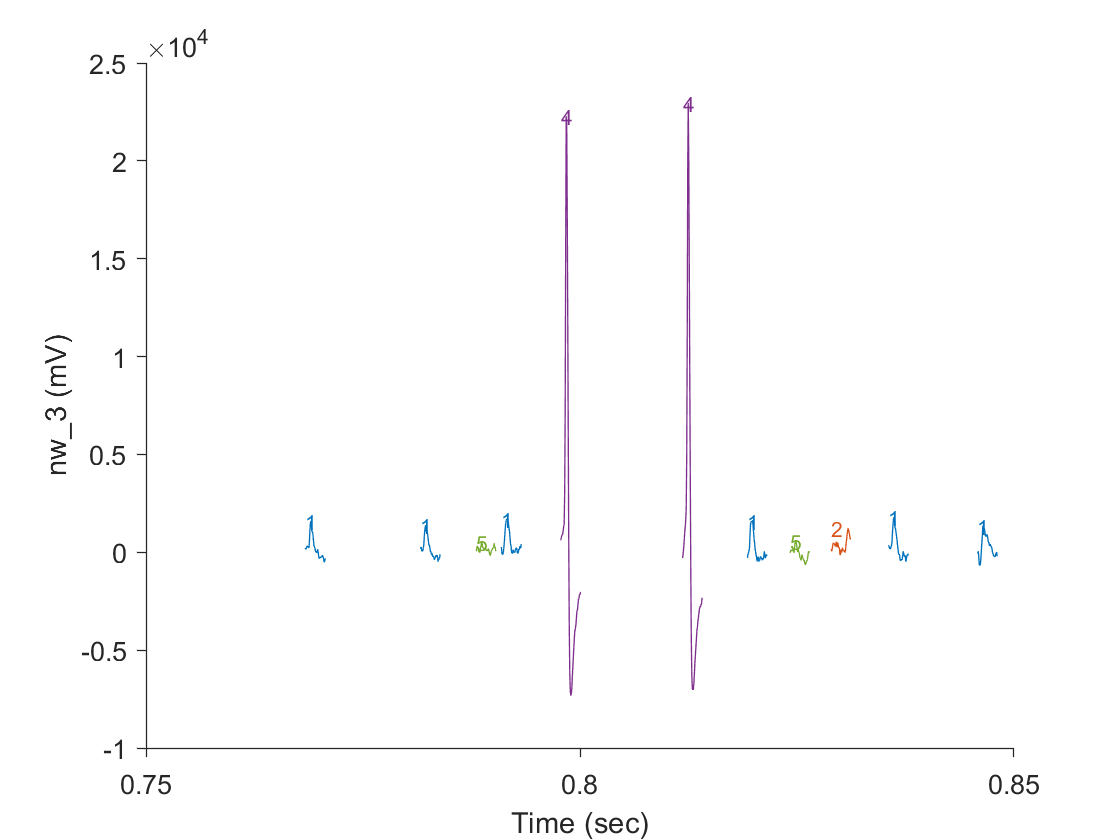

ans = struct with fields:
    fig: [1×1 Figure]
     ax: [1×1 Axes]
     l1: [11×1 Line]



wm1.plot




wm1.MarkerFilter{'value1',1} = false;

wm1.NSpikes 

ans = 5


size(wm1.Traces)

ans =      5    40


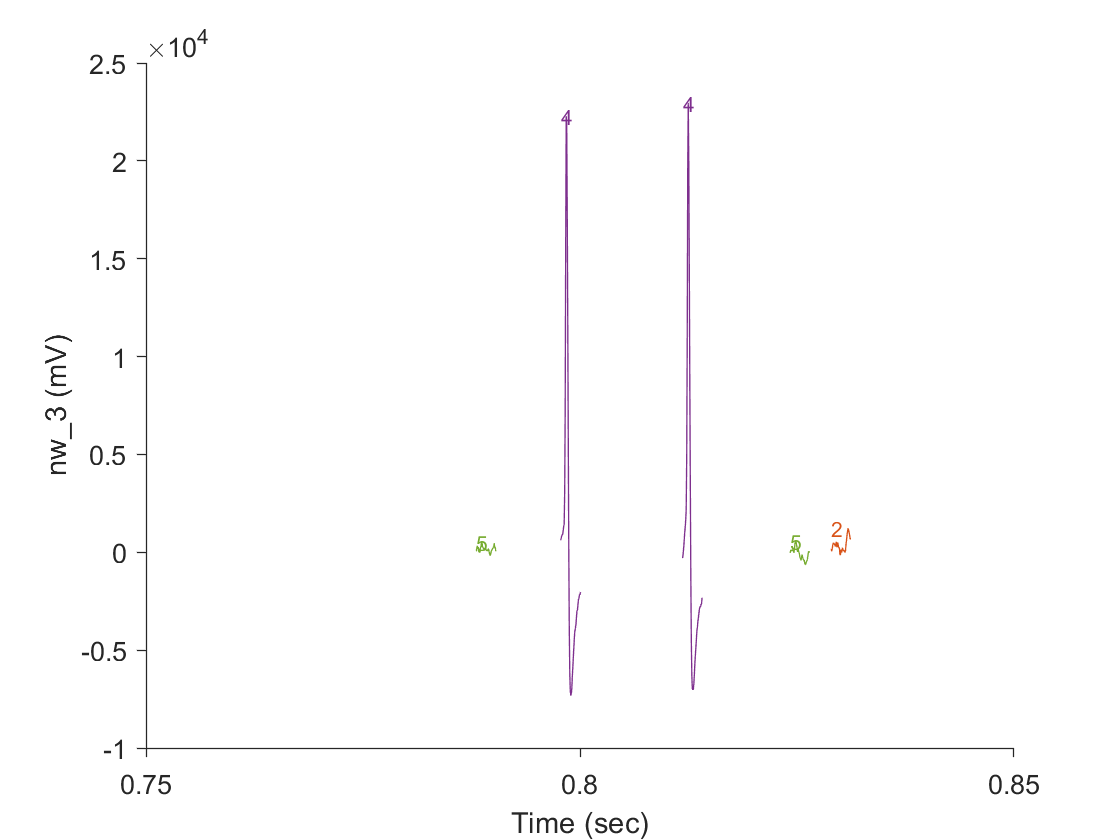

ans = struct with fields:
    fig: [1×1 Figure]
     ax: [1×1 Axes]
     l1: [5×1 Line]



wm1.plot

ans = struct with fields:
    fig: [1×1 Figure]
     ax: [1×1 Axes]
     l1: [11×1 Line]




%% extractTIme method

wm1.MarkerFilter = [];

wm1.plot


wm.overdrawwavemark('OverdrawLimit',50)

Unable to perform assignment because the size of the left side is 0-by-3 and the size of the right side is 4-by-3.

Error in WaveMarkChan/overdrawwavemark (line 217)
                       aveColor(2:end,:) = defaultPlotColors(codes(codes ~= 0));